
%%  Voice Detector - "Is Anyone Talking?"  
% Records your voice, detects speech, and shows cool plots.

%% 1.  Settings  
sampleRate = 16000;       % Audio quality (16kHz is decent)  
recordingDuration = 5;    % How long to record (seconds)  

% How the audio is split for analysis  
frameSize = 0.025;        % 25ms chunks (good for speech)  
frameStep = 0.010;        % 10ms steps (smooth analysis)  

% What counts as "speech"? Adjust if needed.  
minLoudness = 0.1;        % How loud to consider speech  
maxNoisiness = 1.8;       % How "noisy" is considered silence  

%% 2. Record Audio  
fprintf('=== 🎤 Voice Detection ===\n\n');  

=== 🎤 Voice Detection ===



fprintf('Recording for %d seconds...\n', recordingDuration);  

Recording for 5 seconds...


fprintf('Get ready to speak in 3...\n'); pause(1);  

Get ready to speak in 3...


fprintf('2...\n'); pause(1);  

2...


fprintf('1...\n'); pause(1);  

1...


fprintf('Speak now!\n');  

Speak now!



mic = audiorecorder(sampleRate, 16, 1);  % 16-bit, mono  
recordblocking(mic, recordingDuration);  
fprintf('Done recording!\n');  

Done recording!



% Get & normalize audio  
audio = getaudiodata(mic);  
audio = audio / max(abs(audio));  

%% 3.  Analyze Audio (Frame by Frame)  
fprintf('\nAnalyzing... (this is where the magic happens)\n');  


Analyzing... (this is where the magic happens)



% Split audio into small chunks for analysis  
numFrames = floor((length(audio) - round(frameSize * sampleRate)) / round(frameStep * sampleRate)) + 1;  

loudness = zeros(numFrames, 1);  % How loud each chunk is  
noisiness = zeros(numFrames, 1); % How "noisy" each chunk is  
frameTimes = (1:numFrames) * frameStep; % Time stamps for each frame  

for i = 1:numFrames  
    % Grab a small chunk of audio  
    start = (i-1) * round(frameStep * sampleRate) + 1;  
    chunk = audio(start : start + round(frameSize * sampleRate) - 1);  

    % Measure loudness (energy)  
    loudness(i) = mean(chunk.^2);  

    % Measure noisiness (zero-crossing rate)  
    signFlips = sum(abs(diff(sign(chunk))));  
    noisiness(i) = signFlips / (2 * length(chunk));  
end  


## 4.  Detect Speech



% Set thresholds automatically  
loudEnough = loudness > (minLoudness * max(loudness));  
quietEnough = noisiness < (maxNoisiness * mean(noisiness));  

% Speech = loud AND not too noisy  
isSpeaking = loudEnough & quietEnough;  

% Smooth out detection (so it's less jittery)  
smoothedSpeech = movmean(double(isSpeaking), 5) > 0.5;  

%% 5.  Show Results  
fprintf('\n=== Results ===\n');  


=== Results ===



% Find speech segments  
speechTimes = [];  
currentlySpeaking = false;  

for i = 1:length(smoothedSpeech)  
    if smoothedSpeech(i) && ~currentlySpeaking  
        % Speech starts  
        currentlySpeaking = true;  
        startTime = (i-1) * frameStep;  
    elseif ~smoothedSpeech(i) && currentlySpeaking  
        % Speech ends  
        currentlySpeaking = false;  
        endTime = i * frameStep;  
        speechTimes = [speechTimes; startTime endTime];  
    end  
end  

% If still speaking at the end  
if currentlySpeaking  
    speechTimes = [speechTimes; startTime recordingDuration];  
end  

% Print speech segments  
fprintf('Detected speech segments:\n');  

Detected speech segments:


for i = 1:size(speechTimes, 1)  
    duration = speechTimes(i,2) - speechTimes(i,1);  
    fprintf('  Segment %d: %.2f - %.2f sec (%.2f sec)\n', ...  
            i, speechTimes(i,1), speechTimes(i,2), duration);  
end  

  Segment 1: 0.05 - 0.20 sec (0.15 sec)
  Segment 2: 0.26 - 0.44 sec (0.18 sec)
  Segment 3: 0.53 - 0.78 sec (0.25 sec)
  Segment 4: 0.88 - 1.48 sec (0.60 sec)
  Segment 5: 1.80 - 1.98 sec (0.18 sec)
  Segment 6: 2.07 - 2.12 sec (0.05 sec)
  Segment 7: 2.30 - 2.76 sec (0.46 sec)
  Segment 8: 2.79 - 2.83 sec (0.04 sec)
  Segment 9: 2.86 - 3.06 sec (0.20 sec)
  Segment 10: 3.36 - 3.59 sec (0.23 sec)



totalSpeechTime = sum(speechTimes(:,2) - speechTimes(:,1));  
fprintf('\nTotal speech: %.2f sec (%.1f%% of recording)\n', ...  
        totalSpeechTime, 100 * totalSpeechTime / recordingDuration);  


Total speech: 2.34 sec (46.8% of recording)


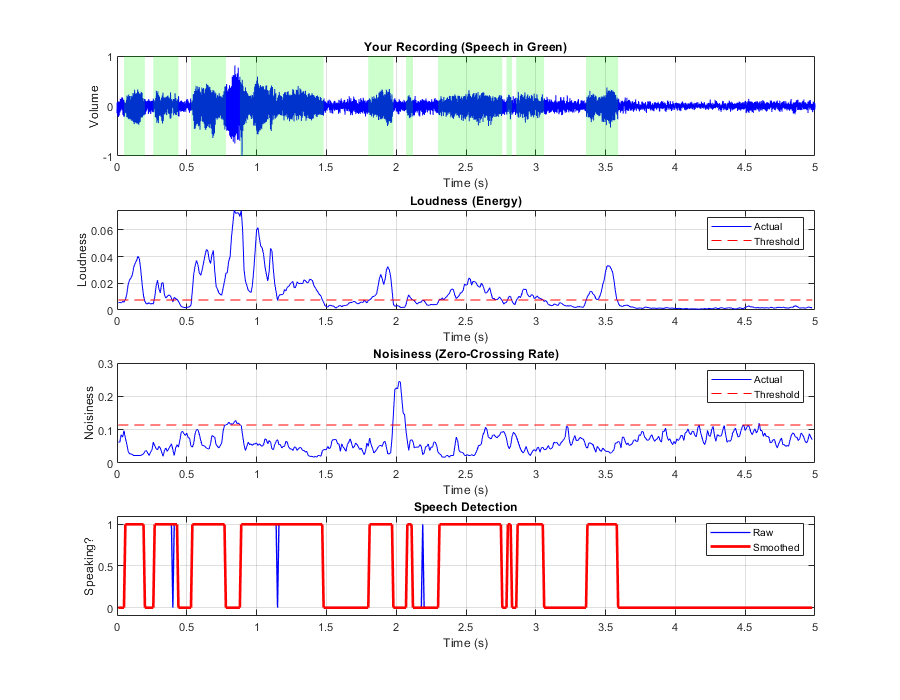


%% 6.  Visualize Everything!  
figure('Name', 'Voice Detection Results', 'Position', [100, 100, 900, 700]);  

% Plot 1: Audio waveform with speech highlighted  
subplot(4,1,1);  
timeAxis = (0:length(audio)-1) / sampleRate;  
plot(timeAxis, audio, 'b');  
title('Your Recording (Speech in Green)');  
xlabel('Time (s)'); ylabel('Volume');  
grid on; hold on;  

% Highlight speech segments - FIXED VERSION  
currentYLim = ylim;  % Correct variable name  
for i = 1:size(speechTimes, 1)  
    x = [speechTimes(i,1), speechTimes(i,1), speechTimes(i,2), speechTimes(i,2)];  
    y = [currentYLim(1), currentYLim(2), currentYLim(2), currentYLim(1)];  
    fill(x, y, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');  
end  
hold off;  

% Plot 2: Loudness over time  
subplot(4,1,2);  
plot(frameTimes, loudness, 'b');  
hold on;  
loudThresh = minLoudness * max(loudness);  
plot([frameTimes(1), frameTimes(end)], [loudThresh, loudThresh], 'r--');  
title('Loudness (Energy)');  
xlabel('Time (s)'); ylabel('Loudness');  
legend('Actual', 'Threshold', 'Location', 'northeast');  
grid on; hold off;  

% Plot 3: Noisiness over time  
subplot(4,1,3);  
plot(frameTimes, noisiness, 'b');  
hold on;  
noiseThresh = maxNoisiness * mean(noisiness);  
plot([frameTimes(1), frameTimes(end)], [noiseThresh, noiseThresh], 'r--');  
title('Noisiness (Zero-Crossing Rate)');  
xlabel('Time (s)'); ylabel('Noisiness');  
legend('Actual', 'Threshold', 'Location', 'northeast');  
grid on; hold off;  

% Plot 4: Final speech detection  
subplot(4,1,4);  
plot(frameTimes, isSpeaking, 'b', 'LineWidth', 1);  
hold on;  
plot(frameTimes, smoothedSpeech, 'r', 'LineWidth', 2);  
title('Speech Detection');  
xlabel('Time (s)'); ylabel('Speaking?');  
ylim([-0.1 1.1]);  
legend('Raw', 'Smoothed', 'Location', 'northeast');  
grid on; hold off;   